# `The freqtag pipeline: A principled approach to analyzing electrophysiological time series in frequency tagging paradigms `

## 1-Load the 3-D file (129 electrodes x 3901 time points x 39 trials)

    - Each trial contains  400ms pre- and 7400ms post-stimulus onset;

    - During each trial, two stimuli flickering at diffrent frequencies overlapped in space (5hz and 6Hz);

    -Describe flickering stimuli here!

load('freqtag.mat') 
dataset = outmat; %Renaming the file for simplification purposes

## 2-Plot the data, averaging the trials

    -The first visualization serves as a sanity check by plotting the data in a time series domain (i.e. ERP).

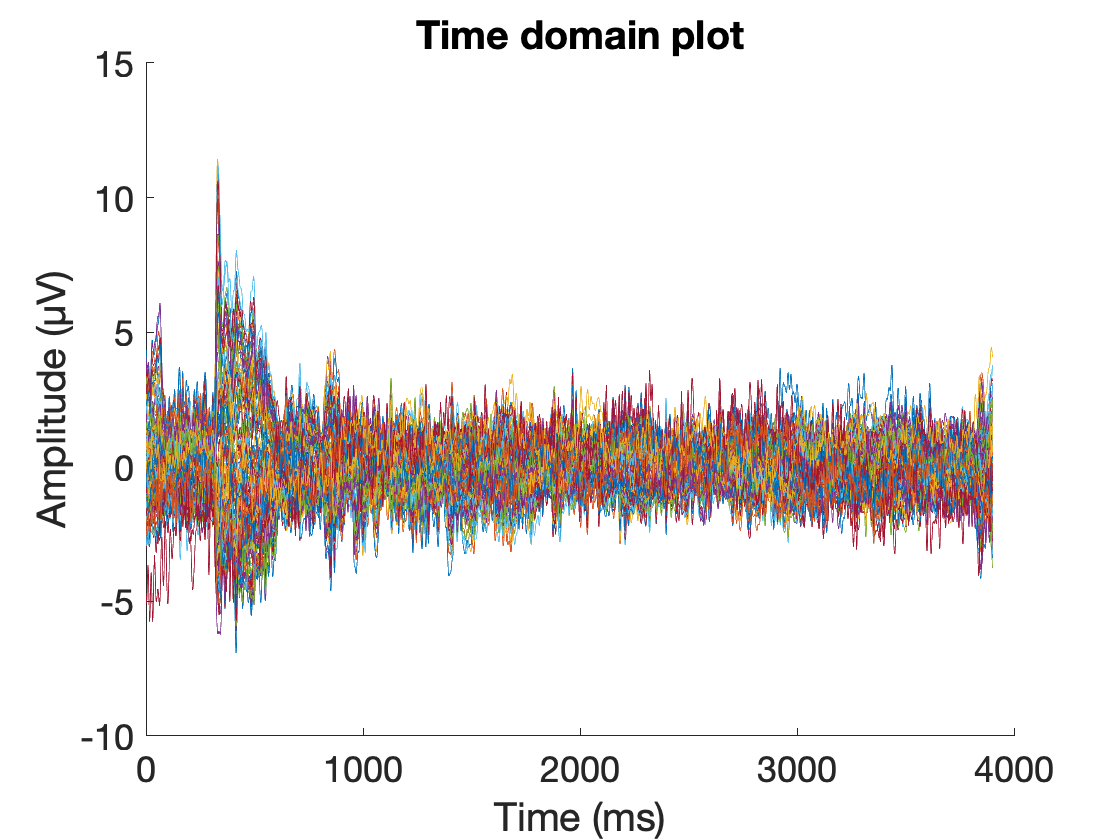

figure(1), plot(mean(dataset,3)') %%Average the third dimension (trial dimension), plot all asensors

ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off';   %remove the box around the plot
xlabel('Time (ms)'), ylabel('Amplitude (μV)'); %label the axis 
title([ 'Time domain plot' ])

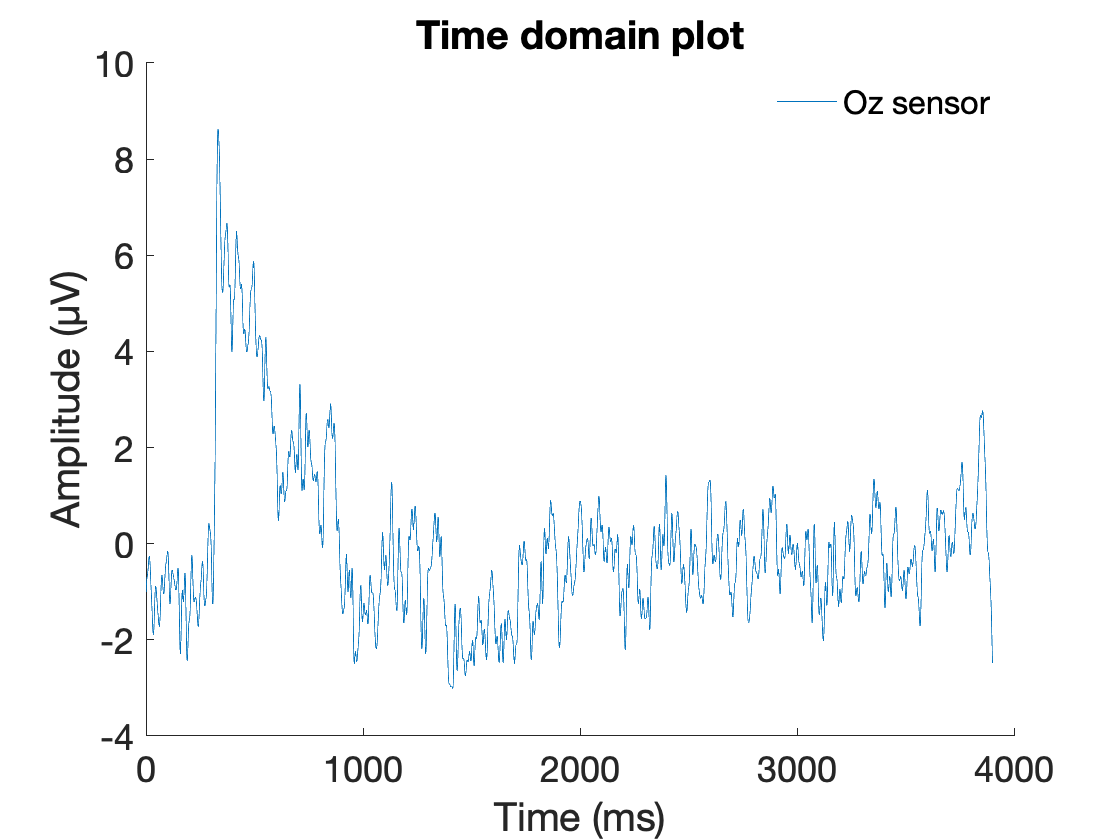


figure(2), plot(mean(dataset(75,:,:), 3)') %%select Oz sensor, sensor #75 (sensors are the first dimension of the 3-D data)

ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off';   %remove the box around the plot
xlabel('Time (ms)'), ylabel('Amplitude (μV)');  %label the axis 
title([ 'Time domain plot' ]);
legend ('Oz sensor'), legend boxoff; %add legend

## 3-Define all frequencies contained in the data, see section 3.1 for a guide on how to delimit the frequency axis

    -The frequency resolution is 0.1282 (1/epoch duration(s)= 1/7.8 = 0.1282);

    -Every frequency bin is 0.1282 apart from each other;

    -The sample rate is 500Hz. Following the Nyquist Theorem, there are 500/2 (250) frequencies in the data;

    -Between 0Hz and 250Hz, in steps of 0.1282, there are 1951 distinguishable frequencies;

    -The frequencies contained in any data can be described as: 0:1/epoch duration(s):Sampling rate/2.

faxisall = 0:0.1282:250;

## 4-Eliminate unnecessary frequencies

    -Given that from all 1951 frequencies, only some are brain related, we can eliminated the very slow and the super fast frequencies.

faxis = faxisall(12:2:265);

## 5-Run FFT on the data

    -The freqtag_FFT function takes a 2-D matrix, therefore the data has to be average in its third dimension;

    -The fft is calculated across the trials;

    -The second argument is the sampling rate;

    -pow, phase, freqs are the three output arguments. They are the results of the fft function and can be used to plot the results.

[pow, phase, freqs] = freqtag_FFT(mean(dataset,3), 500); %The fft function takes a 2-D matrix, it is necessary to average over the trials (third dimension)

## 6-Plot the FFT results

    -Plot the power for each frequency, selecting the frequencies between 0 and 25 (1:196);

    -Use the outputs of the freqtag_FFT function: "freqs" and "pow";

    -Plot all sensors (each line is a sensor).

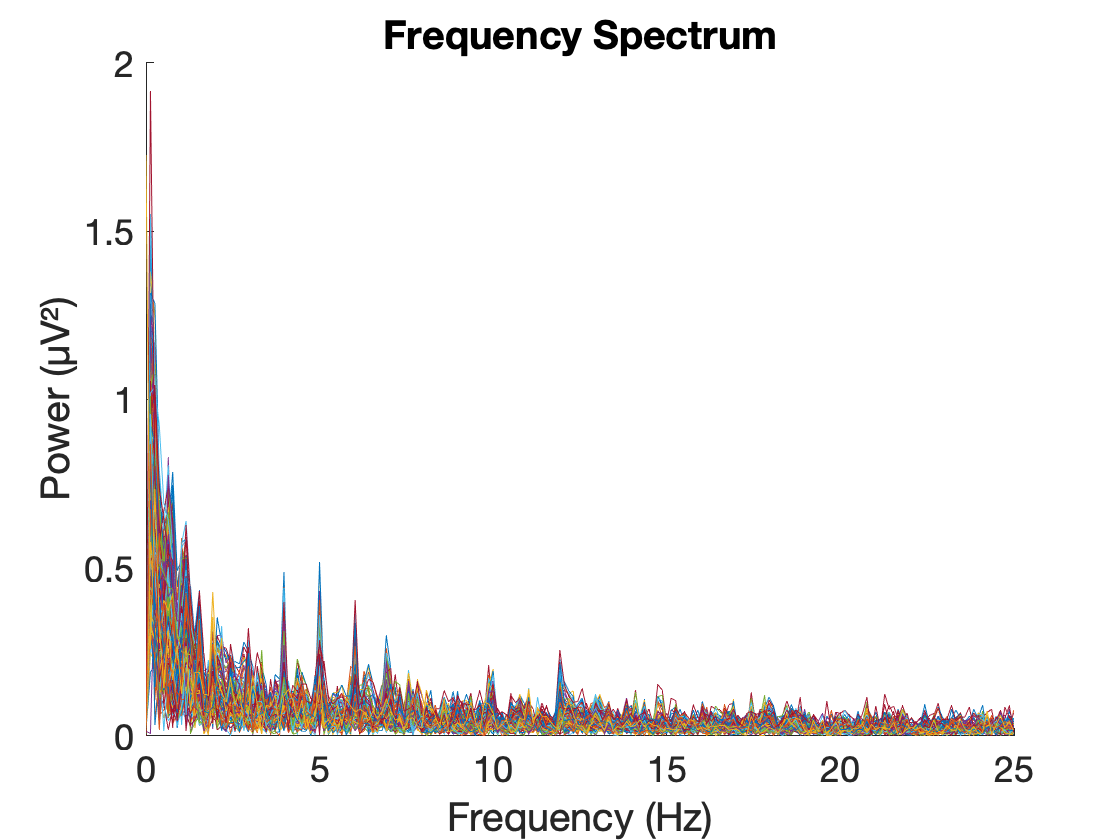

figure(3), plot(freqs(1:196), pow(:, 1:196))   
                                            
ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off';   %remove the box around the plot
xlabel('Frequency (Hz)'), ylabel('Power (μV²)') %label the axis
title([ 'Frequency Spectrum' ])

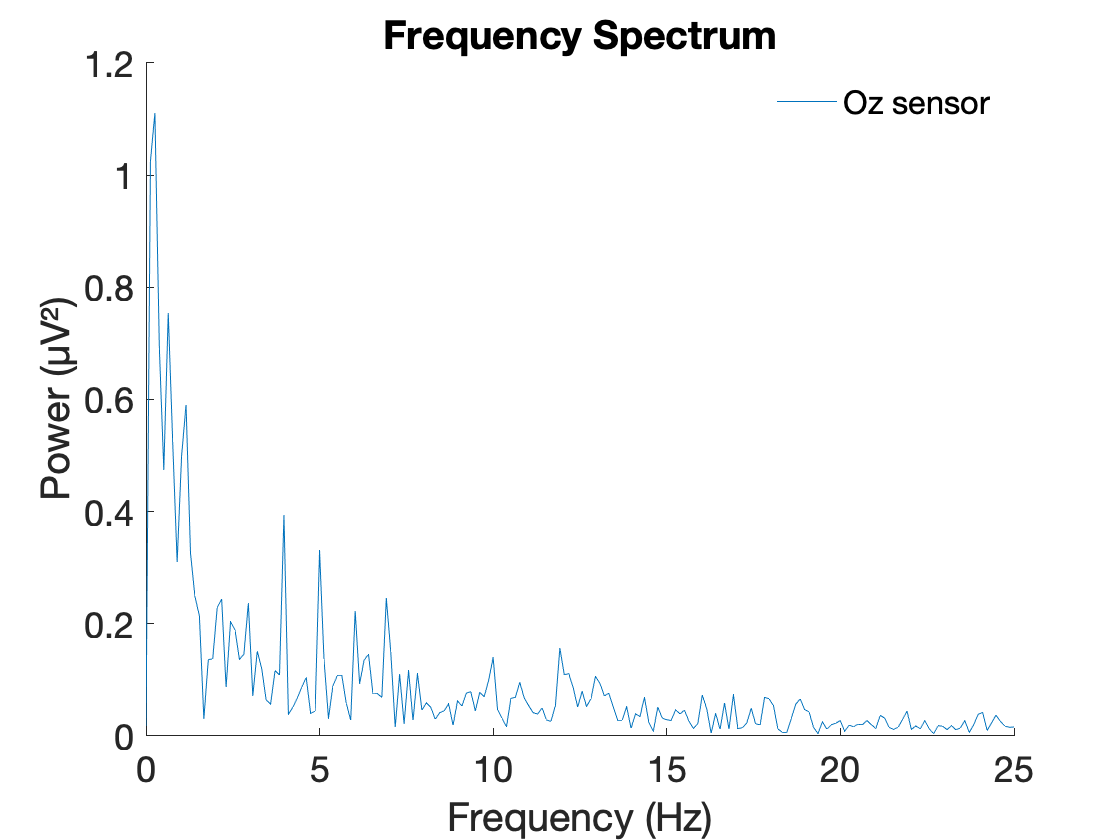


figure(4), plot(freqs(1:196), pow(75, 1:196)) %select Oz sensor (sensor #75)

ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off' ;  %remove the box around the plot
xlabel('Frequency (Hz)'), ylabel('Power (μV²)') %label the axis
title([ 'Frequency Spectrum' ])
legend ('Oz sensor'), legend boxoff %add legend

## 7-Run FFT on single-trials

    -Instead of running the fft across the trials, each trial will have its own spectrum. After computing the fft for all trials, the spectrum will be averaged across the trials;

    -The freqtag3D_FFT takes three input arguments: the dataset, the time points in which the fft is to be computed and the sample rate;

    - "spec" is the output argument that contains a 2-D vector: sensors-by-power.

[spec] = freqtag3D_FFT(dataset, 1:3901, 500); %No need to average over the third dimension here.

## 8-Plot the FFT on single trials results

    -Plot the power for each frequency, select the frequencies between 0 and 25Hz (1:196);

    -The x-axis is the variable that contains the frequencies in the data set: "faxisall';

    -The y-axis is the output argument of the freqtag3D_FFT function, the "spec" variable.

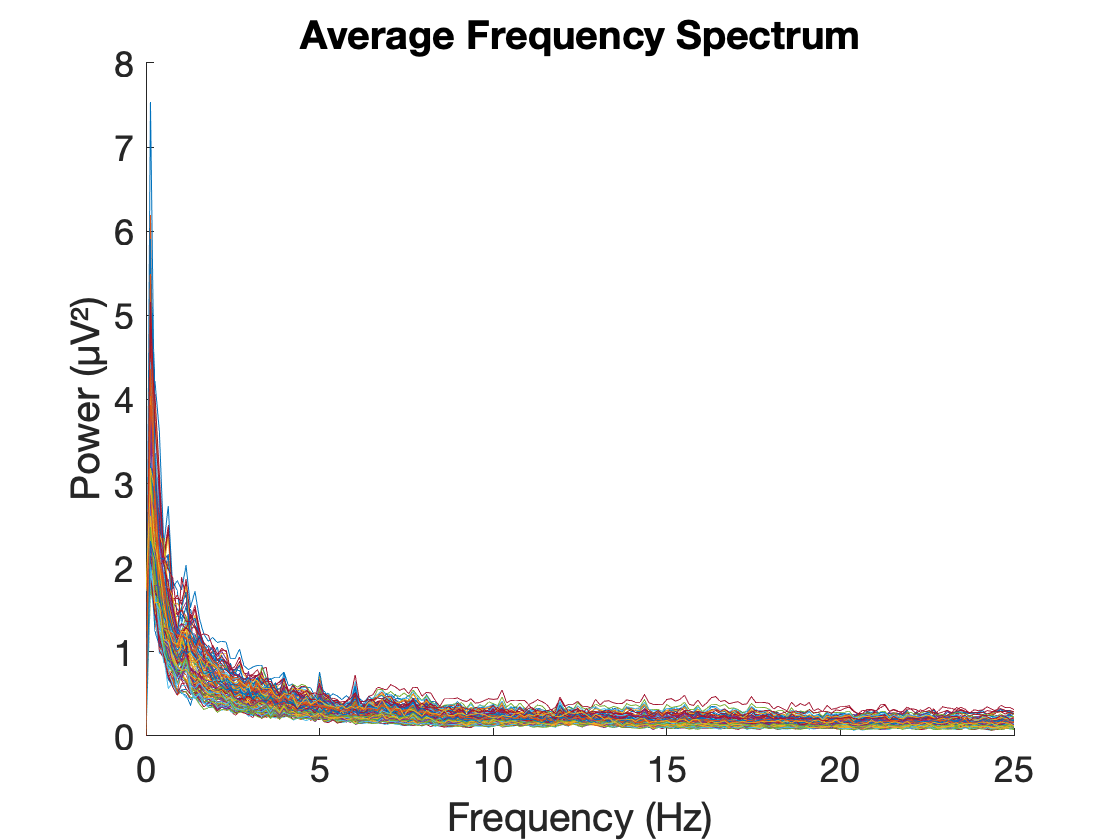

figure(5), plot(faxisall(:, 1:196), spec(:, 1:196))   %plot the all sensors 

ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off';   %remove the box around the plot
xlabel('Frequency (Hz)'), ylabel('Power (μV²)') %label the axis
title([ 'Average Frequency Spectrum' ])

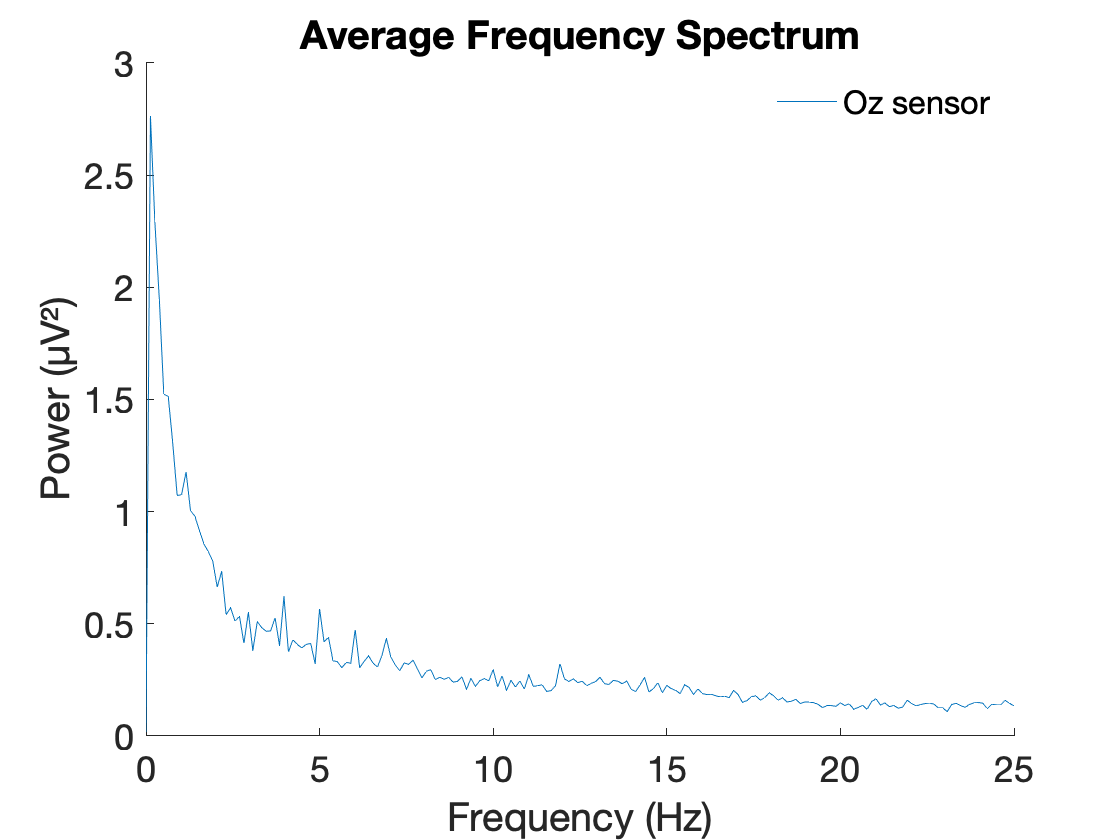


figure(6), plot(faxisall(:, 1:196), spec(75, 1:196))  %select Oz sensor (sensor #75)

ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off';   %remove the box around the plot
xlabel('Frequency (Hz)'), ylabel('Power (μV²)') %label the axis
title([ 'Average Frequency Spectrum' ])
legend ('Oz sensor'), legend boxoff   %add legend

## 9-Run Hilbert Transform. First, selecting the 5Hz tagging frequency. Second, selecting the 6Hz frequency

    -The freqtag_hilb function takes a 2-D data (sensors-br-time points), the stimulus frequency rate in Hz (taggingfreq), the order of the Butterworth filter (filterorder), the sensor to be plotted alongside with the imaginary and real part of the data (sensor2plot), the option to plot or not to plot such information (plotfag) and the sampling rate (fsamp) as input arguments;

    -To feed the function, the dataset is averaged in the third dimension (trial dimension) to become a 2-D matrix;

    -As it is written, the function will plot the sensor Oz (sensor #75), but that can be modified according to the dataset to be analyzed. Although it is advisable to always visualize the data, the reader might turn this plot off by selecting zero or [] in the "plotfag" input argument;

    -In this plot the blue line is the filtered data, the red line is the imaginary part an the black line is the real part;

    -The function should be run for each presentation rate (taggingfreq). Warning: if the output arguments have the same name, they will be subscribed. 

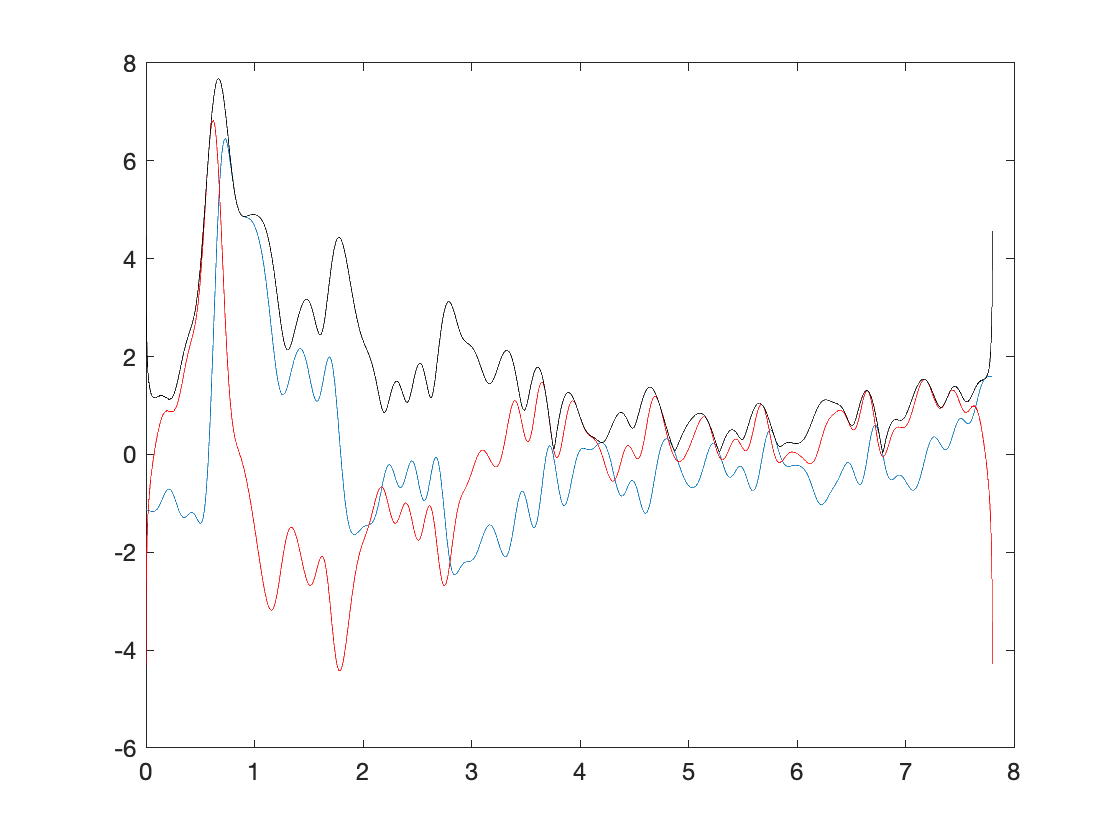

[power5, phase5, complex5] = freqtag_HILB(mean(dataset,3), 5, 4, 75, 1, 500);

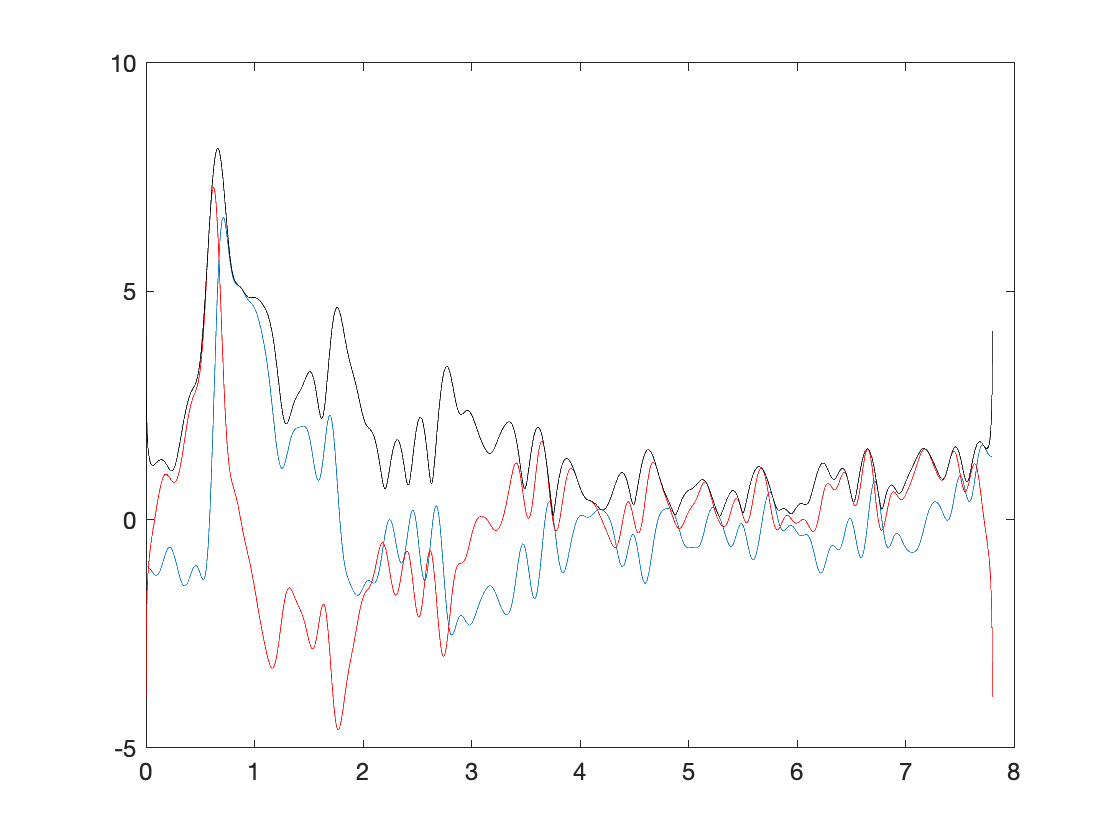

[power6, phase6, complex6] = freqtag_HILB(mean(dataset,3), 6, 4, 75, 1, 500);

## 10-Plot the Hilbert Transform results

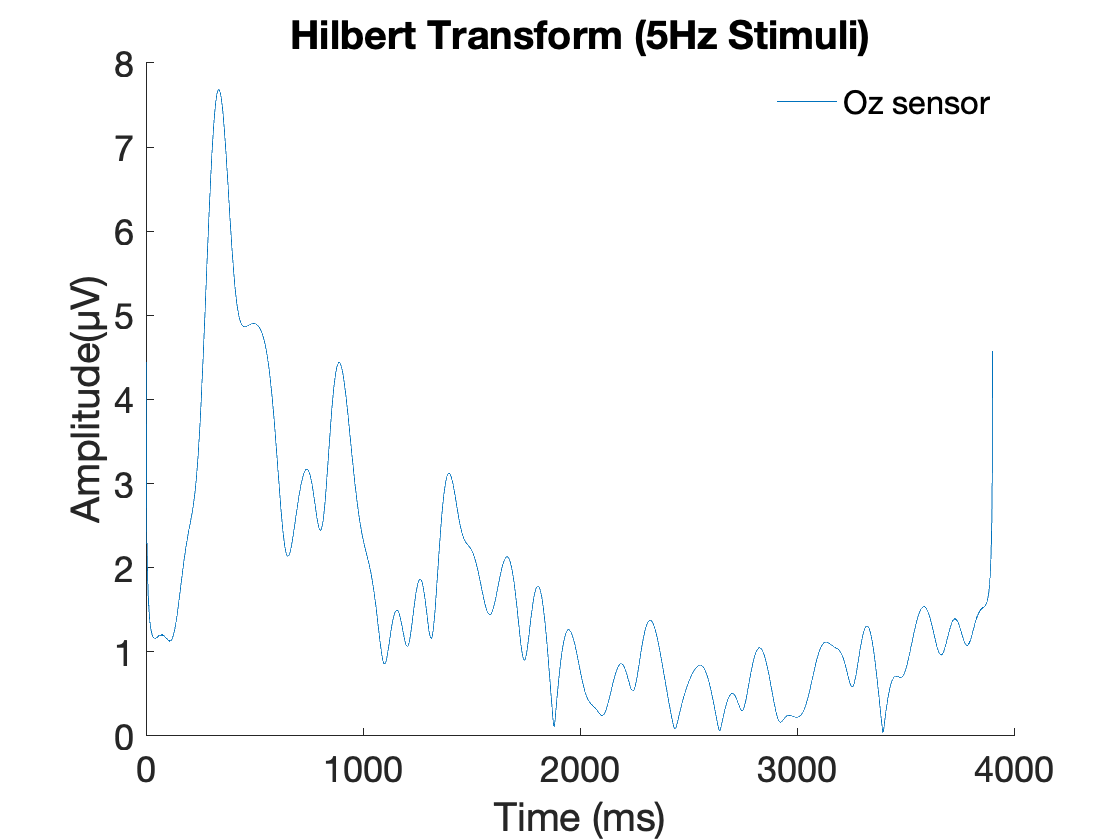

figure(7), plot(power5(75, :)')   %select Oz sensor (sensor #75)

ax = gca;          %editing the plot
ax.FontSize = 18;  %set the font size
ax.Box = 'off';    %remove the box around the plot
xlabel('Time (ms)'), ylabel('Amplitude(μV)') %label the axis
title([ 'Hilbert Transform (5Hz Stimuli)' ])
legend ('Oz sensor'), legend boxoff  %add legend

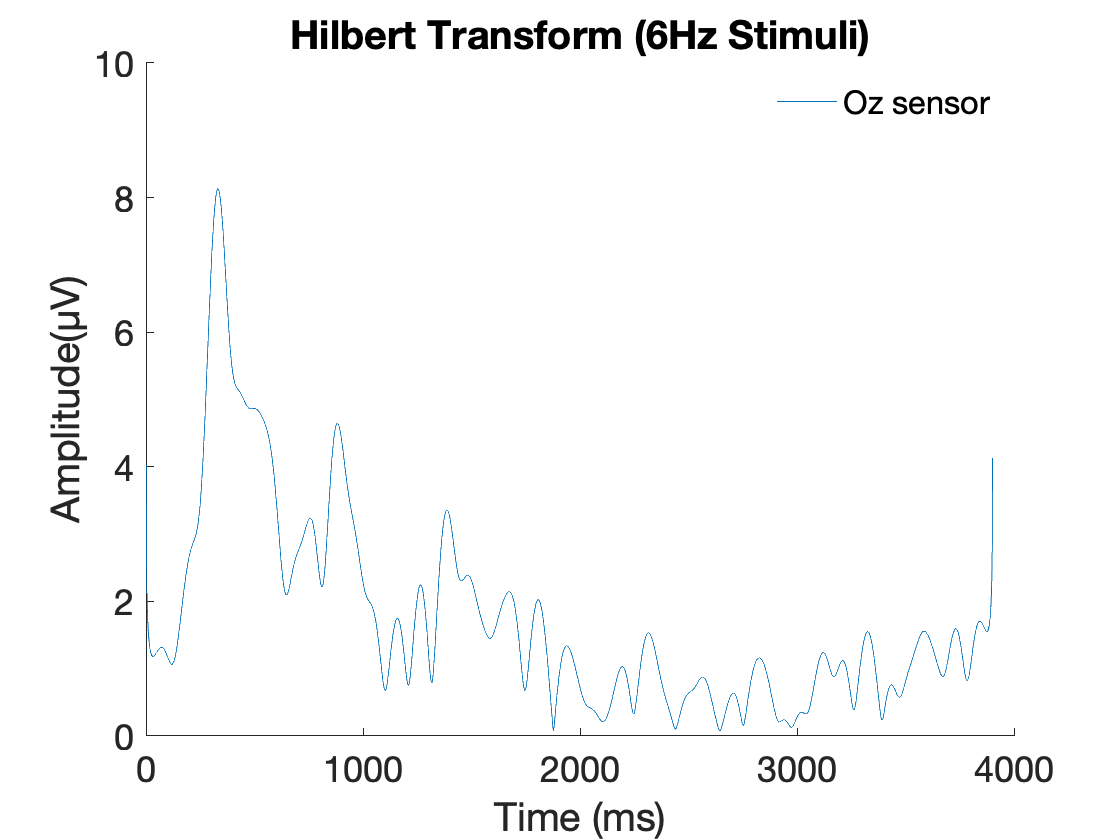


figure(8), plot(power6(75, :)')   %select Oz sensor

ax = gca;          %editing the plot
ax.FontSize = 18;  %set the font size
ax.Box = 'off';    %remove the box around the plot
xlabel('Time (ms)'), ylabel('Amplitude(μV)') %label the axis
title([ 'Hilbert Transform (6Hz Stimuli)' ])
legend ('Oz sensor'), legend boxoff  %add legend

## 11-Close all figures and clean the worskpace

close all
clear all